% test_frequency_split_fixed.m
% 测试频段拆分函数（增加数值稳定性处理）

clear; clc; close all;

%% 参数设置
fs = 10000;          % 采样率 (Hz)
duration = 2;        % 信号时长 (s)
t = (0:1/fs:duration)';
N = length(t);

%% 生成测试信号：包含三个不同频率成分
f1 = 80;   A1 = 1.0;
f2 = 200;  A2 = 0.8;
f3 = 600;  A3 = 0.5;
x = A1*sin(2*pi*f1*t) + A2*sin(2*pi*f2*t) + A3*sin(2*pi*f3*t);
% 添加少量噪声
x = x + 0.05*randn(size(x));

%% 定义频段划分 (Hz) - 避免过窄过渡带
bands = [50, 120;      % 频段1: 包含 80Hz
         150, 250;      % 频段2: 包含 200Hz
         500, 700];     % 频段3: 包含 600Hz
num_bands = size(bands, 1);

%% 调用拆分函数（使用更稳健的零相位滤波）
order = 4;   % 降低阶数，提高数值稳定性（原6改为4）
[x_bands, filters, ~] = split_frequency_bands_robust(x, fs, bands, order);

% 检查是否有 NaN
if any(isnan(x_bands(:)))
    error('拆分后的信号包含 NaN，请降低滤波器阶数或放宽频段边界。');
end

%% 计算各频段信号与理论分量的相关系数（忽略前0.2秒暂态）
ignore_samples = round(0.2*fs);
x1_true = A1*sin(2*pi*f1*t);
x2_true = A2*sin(2*pi*f2*t);
x3_true = A3*sin(2*pi*f3*t);

% 避免常数列导致相关系数无效
corr1 = 0; corr2 = 0; corr3 = 0;
if std(x_bands(ignore_samples:end,1)) > 1e-6
    corr1 = corrcoef(x_bands(ignore_samples:end,1), x1_true(ignore_samples:end));
    corr1 = corr1(1,2);
end
if std(x_bands(ignore_samples:end,2)) > 1e-6
    corr2 = corrcoef(x_bands(ignore_samples:end,2), x2_true(ignore_samples:end));
    corr2 = corr2(1,2);
end
if std(x_bands(ignore_samples:end,3)) > 1e-6
    corr3 = corrcoef(x_bands(ignore_samples:end,3), x3_true(ignore_samples:end));
    corr3 = corr3(1,2);
end

fprintf('=== 频段拆分质量评估 ===\n');

=== 频段拆分质量评估 ===


fprintf('频段1 (%.0f-%.0f Hz) 与 理论 80Hz 相关系数: %.4f\n', bands(1,1), bands(1,2), corr1);

频段1 (50-120 Hz) 与 理论 80Hz 相关系数: 0.9978


fprintf('频段2 (%.0f-%.0f Hz) 与 理论 200Hz 相关系数: %.4f\n', bands(2,1), bands(2,2), corr2);

频段2 (150-250 Hz) 与 理论 200Hz 相关系数: 0.9985


fprintf('频段3 (%.0f-%.0f Hz) 与 理论 600Hz 相关系数: %.4f\n', bands(3,1), bands(3,2), corr3);

频段3 (500-700 Hz) 与 理论 600Hz 相关系数: 0.9992


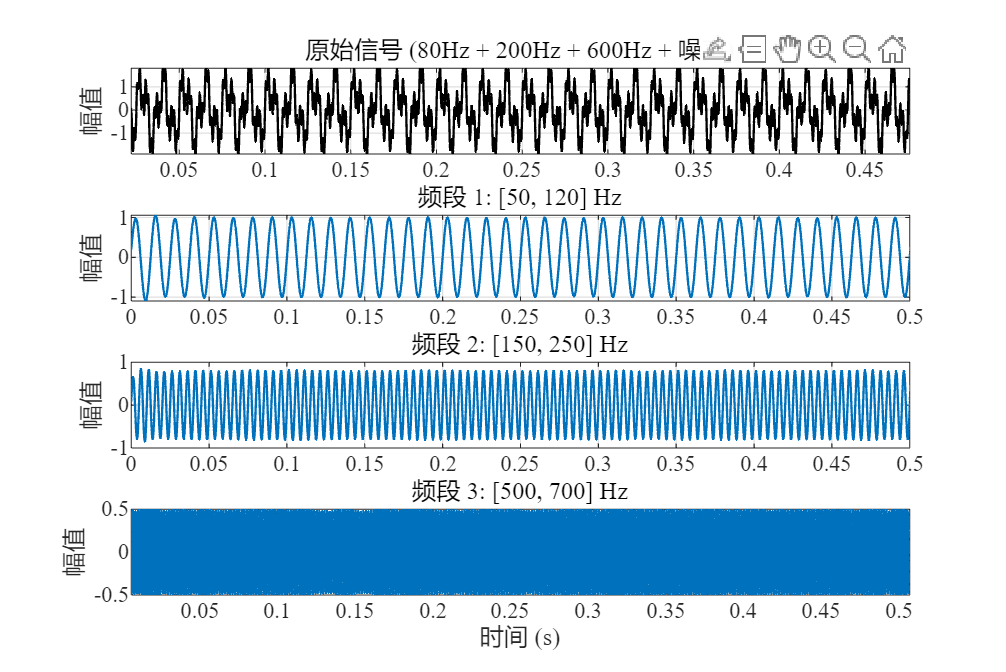


%% 绘图（时域）
figure('Name', '频段拆分结果', 'Position', [100,100,1200,800]);

subplot(num_bands+1,1,1);
plot(t, x, 'k', 'LineWidth', 1);
title('原始信号 (80Hz + 200Hz + 600Hz + 噪声)');
ylabel('幅值'); grid on; xlim([0, 0.5]);

for k = 1:num_bands
    subplot(num_bands+1,1,k+1);
    plot(t, x_bands(:,k), 'LineWidth', 1);
    title(sprintf('频段 %d: [%.0f, %.0f] Hz', k, bands(k,1), bands(k,2)));
    ylabel('幅值'); grid on; xlim([0, 0.5]);
end
xlabel('时间 (s)');

subplot(4,1,1)
xlim([0.022 0.476])
ylim([-1.9 1.8])
subplot(4,1,4)
xlim([0.006 0.507])
ylim([-0.5 0.5])

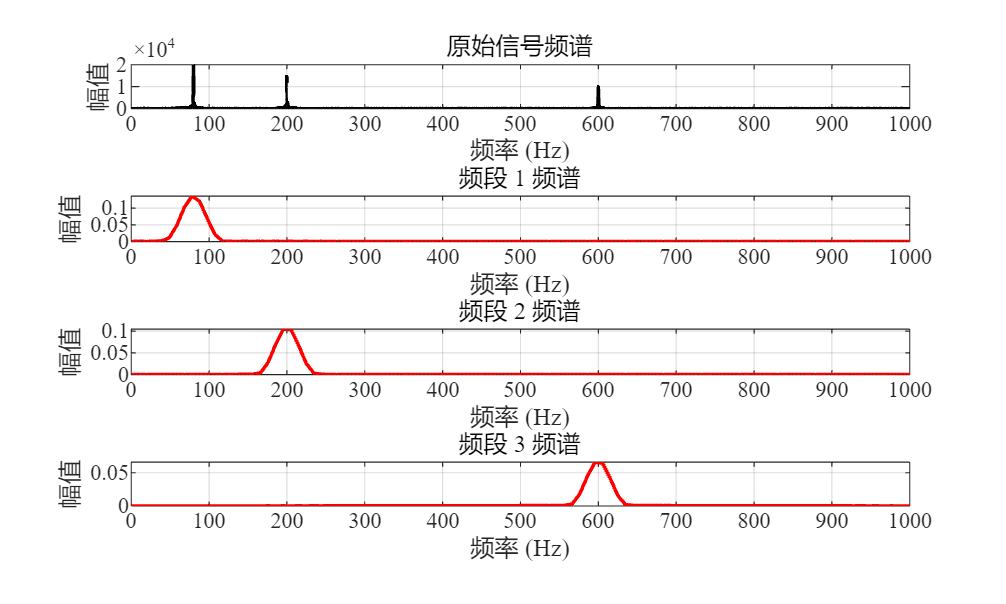


%% 频谱对比（使用 pwelch 前先去除 NaN）
figure('Name', '频谱对比', 'Position', [100,100,1000,600]);
NFFT = 2^nextpow2(N);
f = fs/2 * linspace(0,1,NFFT/2+1);

% 原始信号频谱
X = fft(x, NFFT);
subplot(num_bands+1,1,1);
plot(f, 2*abs(X(1:NFFT/2+1)), 'k');
title('原始信号频谱'); xlabel('频率 (Hz)'); ylabel('幅值');
xlim([0, 1000]); grid on;

% 各频段拆分信号频谱（使用 pwelch 且忽略 NaN）
for k = 1:num_bands
    subplot(num_bands+1,1,k+1);
    sig = x_bands(:,k);
    % 移除 NaN（如果存在）
    if any(isnan(sig))
        sig = fillmissing(sig, 'linear');
        warning('频段 %d 信号含有 NaN，已线性插值填充。', k);
    end
    % 使用 pwelch 计算功率谱
    [pxx, f_psd] = pwelch(sig, hamming(512), 256, 1024, fs);
    plot(f_psd, sqrt(pxx), 'r');  % 显示幅值谱
    title(sprintf('频段 %d 频谱', k));
    xlabel('频率 (Hz)'); ylabel('幅值');
    xlim([0, 1000]); grid on;
end


%% 评估各频段能量泄漏（仅当信号无 NaN 时）
total_energy_band = zeros(num_bands,1);
outband_energy_ratio = zeros(num_bands,1);
for k = 1:num_bands
    sig = x_bands(:,k);
    if any(isnan(sig))
        fprintf('频段 %d 包含 NaN，跳过泄漏计算。\n', k);
        continue;
    end
    total_energy_band(k) = sum(sig.^2);
    [psd, f_psd] = pwelch(sig, hamming(512), 256, 1024, fs);
    df = f_psd(2)-f_psd(1);
    inband_idx = (f_psd >= bands(k,1) & f_psd <= bands(k,2));
    outband_energy = sum(psd(~inband_idx)) * df;
    total_energy_psd = sum(psd) * df;
    if total_energy_psd > 0
        outband_energy_ratio(k) = outband_energy / total_energy_psd;
        fprintf('频段%d 带外能量比例: %.2f%%\n', k, outband_energy_ratio(k)*100);
    else
        fprintf('频段%d 总能量为零，无法计算泄漏。\n', k);
    end
end

频段1 带外能量比例: 0.28%
频段2 带外能量比例: 0.04%
频段3 带外能量比例: 0.03%



%% 信号重建误差
x_reconstructed = sum(x_bands, 2);
reconstruction_error = x - x_reconstructed;
fprintf('\n重建误差 RMS: %.4f (应接近 0)\n', rms(reconstruction_error));


重建误差 RMS: 0.0726 (应接近 0)


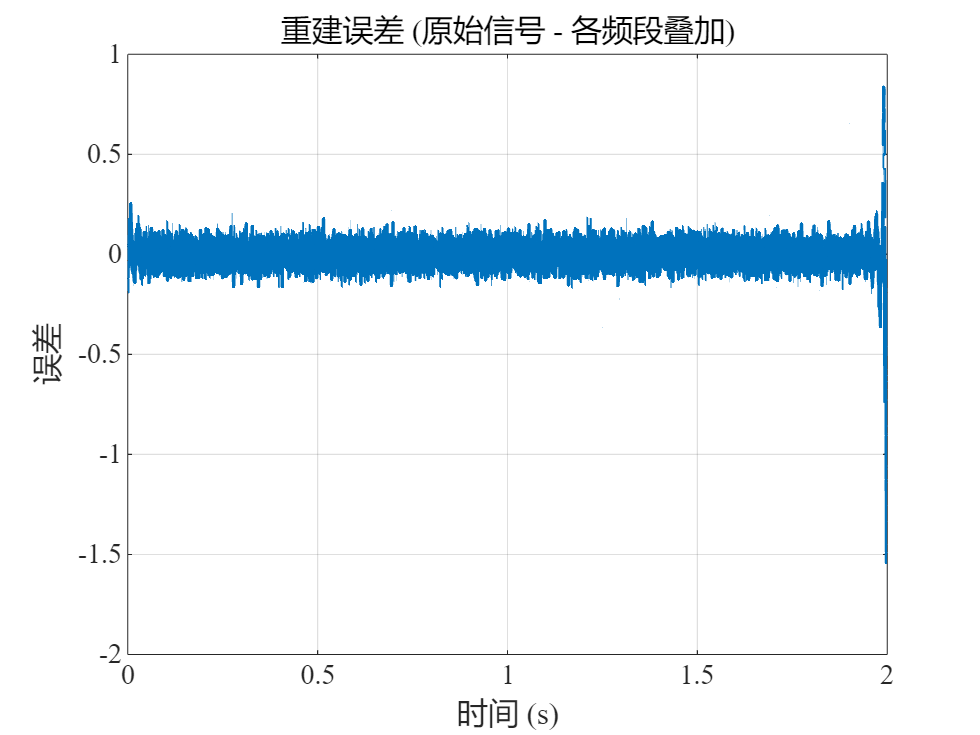


figure;
plot(t, reconstruction_error);
title('重建误差 (原始信号 - 各频段叠加)');
xlabel('时间 (s)'); ylabel('误差'); grid on;


%% ========== 稳健的频段拆分函数（嵌入在此，也可单独保存） ==========
function [band_signals, filters, final_states] = split_frequency_bands_robust(signal, fs, bands, order)
    N = length(signal);
    K = size(bands, 1);
    band_signals = zeros(N, K);
    filters = cell(K, 1);
    final_states = cell(K, 1);
    
    for k = 1:K
        Wn = bands(k, :) / (fs/2);
        Wn(Wn <= 0) = 0.001;
        Wn(Wn >= 1) = 0.999;
        % 尝试设计滤波器，若数值不稳定则降低阶数
        stable = false;
        current_order = order;
        while ~stable && current_order >= 2
            [b, a] = butter(current_order, Wn, 'bandpass');
            % 检查极点是否在单位圆内
            if max(abs(roots(a))) < 1
                stable = true;
            else
                current_order = current_order - 1;
                warning('频段 %d 滤波器阶数 %d 不稳定，降低至 %d', k, current_order+1, current_order);
            end
        end
        if ~stable
            error('无法设计稳定的滤波器，请放宽频段范围或降低采样率。');
        end
        filters{k}.b = b;
        filters{k}.a = a;
        % 使用 filtfilt 进行零相位滤波（注意边界效应）
        band_signals(:, k) = filtfilt(b, a, signal);
        % 保存最终状态（用于连续滤波，此处为占位）
        [~, final_states{k}] = filter(b, a, signal);
    end
end